# Analyse properties of conserved moieties

tutorial_initConservedMoietyPaths

modelName = 'DAS'

projectDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties'

dataDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/data/models/'

softwareDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/software/'

visDataDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/data/visualisation/'

resultsDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/results/DAS_ConservedMoieties/'

rxnfileDir = '/home/rfleming/work/sbgCloud/code/fork-COBRA.tutorials/analysis/conservedMoieties/data/mini-ctf/rxns/atomMapped'

if ~recompute
    load([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])
    return
end

Load the atomically resolved models derived from identifyConservedMoieties.m

load([resultsDir modelName '_arm.mat'])

Basic properties of atomically resolved models

disp(arm)

     MRH: [1×1 struct]
    dATM: [1×1 digraph]
    M2Ai: [11×170 double]
    Ti2R: [176×4 double]
    Ti2I: [176×6 double]
     ATG: [1×1 graph]
     M2A: [11×170 double]
     A2R: [114×4 double]
    A2Ti: [114×176 double]
     I2A: [6×170 double]
     A2I: [114×6 double]
     I2C: [6×56 double]
     C2A: [56×170 double]
     A2C: [114×56 double]
     MTG: [1×1 graph]
     I2M: [6×26 double]
     M2I: [20×6 double]
     M2M: [11×26 double]
     M2R: [20×4 double]
       L: [6×11 double]



Load the model, unless it is also saved with the results.

if 0
    load([dataDir modelName '.mat'])
    model = iDopaNeuro;
else
    model=arm.MRH;
end

Identify the stoichiometrically consistent subset of the model

massBalanceCheck=0;
printLevel=1;
[SConsistentMetBool, SConsistentRxnBool1, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model]...
    = findStoichConsistentSubset(model,massBalanceCheck,printLevel);

--- findStoichConsistentSubset START ----
--- Summary of stoichiometric consistency ----
    11	    11	 totals.
     0	     7	 heuristically external.
    11	     4	 heuristically internal:
    11	     4	 ... of which are stoichiometrically consistent.
     0	     0	 ... of which are stoichiometrically inconsistent.
     0	     0	 ... of which are of unknown consistency.
    11	     4	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----


Remove non-atom mapped part of the model, but keep the external reactions

keepRxnBool = getCorrespondingCols(arm.MRH.S, arm.MRH.metAtomMappedBool, true(size(arm.MRH.S,2),1), 'inclusive');
keepRxnBool = keepRxnBool & ~SConsistentRxnBool1;
removeRxnBool = ~(arm.MRH.rxnAtomMappedBool | keepRxnBool);
model = removeRxns(arm.MRH, arm.MRH.rxns(removeRxnBool));

Identify the stoichiometrically consistent subset of the model

massBalanceCheck=1;
printLevel=1;
[SConsistentMetBool, SConsistentRxnBool2, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model]...
    = findStoichConsistentSubset(model,massBalanceCheck,printLevel);

--- findStoichConsistentSubset START ----
--- Summary of stoichiometric consistency ----
    11	    11	 totals.
     0	     7	 heuristically external.
    11	     4	 heuristically internal:
    11	     4	 ... of which are stoichiometrically consistent.
     0	     0	 ... of which are stoichiometrically inconsistent.
     0	     0	 ... of which are of unknown consistency.
---
     0	     0	 heuristically internal and stoichiometrically inconsistent or unknown consistency.
     0	     0	 ... of which are elementally imbalanced (inclusively involved metabolite).
     0	     0	 ... of which are elementally imbalanced (exclusively involved metabolite).
    11	     4	 Confirmed stoichiometrically consistent by leak/siphon testing.
--- findStoichConsistentSubset END ----


Table of model properties

rankN=getRankLUSOL(arm.MRH.S(arm.MRH.metAtomMappedBool,arm.MRH.rxnAtomMappedBool));

Caught error using lusol interface. Proceeding with matlab LU implementation (slower)


rankL=getRankLUSOL(arm.L);

Caught error using lusol interface. Proceeding with matlab LU implementation (slower)


rankdATM=getRankLUSOL(incidence(arm.dATM));

Caught error using lusol interface. Proceeding with matlab LU implementation (slower)


rankATG=getRankLUSOL(incidence(arm.ATG));

Caught error using lusol interface. Proceeding with matlab LU implementation (slower)


rankMTG=getRankLUSOL(incidence(arm.MTG));

Caught error using lusol interface. Proceeding with matlab LU implementation (slower)



TT={'Model', 'm+'  , 'Metabolites', size(arm.MRH.S,1);
       ''     , 'm'   , 'Mapped metabolites', nnz(arm.MRH.metAtomMappedBool);
   ''     , 'n+'  , 'Reactions', size(arm.MRH.S,2);
   ''     , ''    ,  'Internal reactions', nnz(SConsistentRxnBool1);
   ''     , ''    ,  'External reactions', nnz(~SConsistentRxnBool1);
   ''     , 'n'   , 'Mapped reactions', nnz(arm.MRH.rxnAtomMappedBool);
   'Mapped model'     , 'm'   , 'size(model.S,1)', rankN;
   ''     , 'n+k'   , 'size(model.S,2)', size(model.S,2);
   ''     , ''    ,  'Internal reactions', nnz(SConsistentRxnBool2);
   ''     , ''    ,  'External reactions', nnz(~SConsistentRxnBool2);
   ''     , 'r'   , 'Rank(N)', rankN;
   ''     , 'm-r' , 'Row rank deficiency(N)', nnz(arm.MRH.metAtomMappedBool) - rankN;
   ''     , ''    ,  'Isomorphism classes', size(arm.L,1); 
   ''     , ''    ,  'Independent isomorphism classes', rankL; 
   'MTG'  , ''    ,  'Moieties', size(arm.I2M,2); 
   ''     , ''    ,  'Moiety transitions', size(arm.M2I,1); 
   ''     , ''    ,  'Rank(M)', rankMTG; 
  'ATG'   , ''    ,  'Atoms', size(arm.I2A,2); 
   ''     , ''    ,  'Atom transitions', size(arm.A2I,1); 
   ''     , ''    ,  'Rank(A)', rankATG; 
   ''     , ''    ,  'Row rank deficiency(A)', size(arm.I2A,2) - rankATG;
   ''     , ''    ,  'Components', size(arm.C2A,1); 
'dATM'    , ''    ,  'Atoms', size(arm.dATM.Nodes,1); 
   ''     , ''    ,  'Directed atom transition instances', size(arm.dATM.Edges,1); 
   ''     , ''    ,  'Rank(dATM)', rankdATM; 
   ''     , ''    ,  'Row rank deficiency(dATM)', size(arm.dATM.Edges,1) - rankdATM;
   ''     , ''    ,  '', NaN;  
   };
disp(TT)

    {'Model'       }    {'m+'    }    {'Metabolites'                   }    {[ 11]}
    {0×0 char      }    {'m'     }    {'Mapped metabolites'            }    {[ 11]}
    {0×0 char      }    {'n+'    }    {'Reactions'                     }    {[ 11]}
    {0×0 char      }    {0×0 char}    {'Internal reactions'            }    {[  4]}
    {0×0 char      }    {0×0 char}    {'External reactions'            }    {[  7]}
    {0×0 char      }    {'n'     }    {'Mapped reactions'              }    {[  4]}
    {'Mapped model'}    {'m'     }    {'size(model.S,1)'               }    {[  4]}
    {0×0 char      }    {'n+k'   }    {'size(model.S,2)'               }    {[ 11]}
    {0×0 char      }    {0×0 char}    {'Internal reactions'            }    {[  4]}
    {0×0 char      }    {0×0 char}    {'External reactions'            }    {[  7]}
    {0×0 char      }    {'r'     }    {'Rank(N)'                       }    {[  4]}
    {0×0 char      }    {'m-r'   }    {'Row rank deficiency(N)'        }    

## Properties of conserved moieties

[moietyMasses, knownmoietyMasses, unknownElements, Ematrix, elements] = getMolecularMass(moietyFormulae);
[metMasses, knownmetMasses, unknownElements, Ematrix, elements] = getMolecularMass(model.metFormulas);

Compare the distributions of the molecular moietyMasses

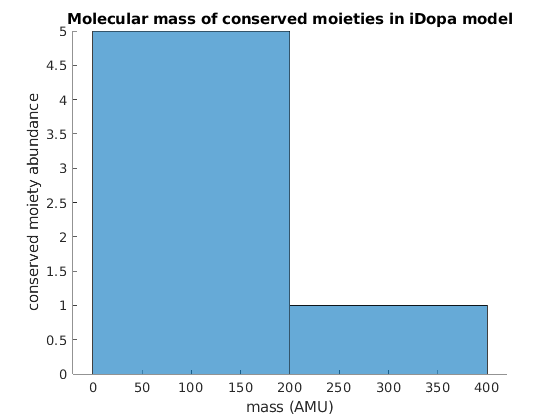

figure
hold on
h = histogram(moietyMasses);
xlabel('mass (AMU)')
ylabel('conserved moiety abundance')
title('Molecular mass of conserved moieties in iDopa model')

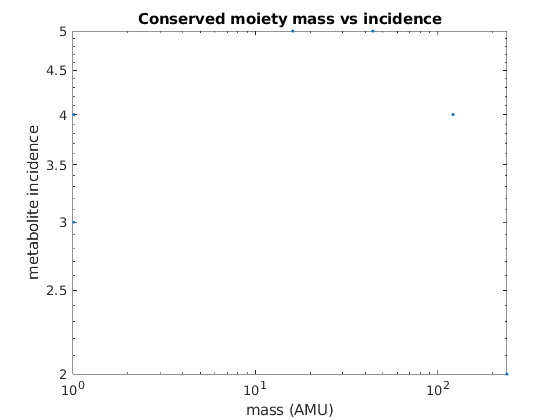

%h2.BinWidth = 0.25;
figure
moietyIncidence = sum(arm.L~=0,2);
loglog(moietyMasses,moietyIncidence,'.')
title('Conserved moiety mass vs incidence')
xlabel('mass (AMU)')
ylabel('metabolite incidence')

The metabolite mass vs mass weighted incidence of moieties in each metabolite should be a straight line trough the origin if all of the moieties that make up a metabolite are present and the formula for the metabolite is correct. Sometimes the metabolite formula is ambiguous, e.g., FULLR in the formula, so the mass will be incorrect.

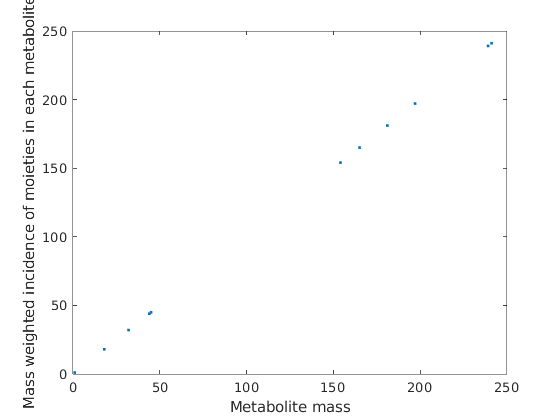

figure
approxMetMasses = arm.L'*moietyMasses;
plot(metMasses,approxMetMasses,'.')
xlabel('Metabolite mass')
ylabel('Mass weighted incidence of moieties in each metabolite')

massDifference = abs(approxMetMasses-metMasses)./metMasses;
bool=massDifference >0.1;
n=1;
C = cell(nnz(bool),6);
for i=1:size(model.S,1)
    if bool(i)
        C(n,:)={i, massDifference(i),model.mets{i},model.metFormulas{i},metMasses(i),approxMetMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','massDifference','mets','metFormula','metMass','approxMetMass'};
disp(T)

Metabolites with mass most similar to the mass of the moiety they contain

[minimalMassMetabolite, minimalMassFraction, numMinimalMassMetabolites] = representativeMolecule(arm.L,moietyFormulae,model.mets);
if ~isfield(model,'metNames')
    model.metNames = model.mets;
end

## High molecular weight moieties that are present in many metabolites.

massWeightedIncidence=diag(moietyMasses)*arm.L*ones(size(arm.L,2),1);
[massWeightedIncidenceSorted, xi] = sort(massWeightedIncidence,'descend');
bool=false(size(arm.L,1),1);
bool(xi(1:min(length(xi),30)))=1;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 6

disp(T)

    index    metabolites    rxns    moietyformula     mass     Minimalmassmetabolite      Name          Formula       Massfraction
    _____    ___________    ____    _____________    ______    _____________________    _________    _____________    ____________

      3           2           6     {'C9H13N5O3'}     239.1          {'dhbpt'}          {'dhbpt'}    {'C9H13N5O3'}             1  
      1           4           8     {'C8H11N'   }    121.09          {'dopa' }          {'dopa' }    {'C8H12NO2' }       0.78585  
      2           5          11     {'CO2'      }     43.99          {'co2'  }          {'co2'  }    {'CO2'      }             1  
      6           5          12     {'

## Moieties that are present in a near maximal number of metabolites.

bool=moietyIncidence>=100;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,2,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 0

disp(T)

## Moieties that are present in a moderate number of metabolites.

bool= moietyIncidence>=10 & moietyIncidence<=100;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 0

disp(T)

## Moieties that are present in a small number of metabolites.

bool= moietyIncidence>2 & moietyIncidence<=10;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 5

disp(T)

    index    metabolites    rxns    moietyformula     mass     Minimalmassmetabolite      Name        Formula       Massfraction
    _____    ___________    ____    _____________    ______    _____________________    ________    ____________    ____________

      1           4           8      {'C8H11N'}      121.09          {'dopa'}           {'dopa'}    {'C8H12NO2'}       0.78585  
      2           5          11      {'CO2'   }       43.99          {'co2' }           {'co2' }    {'CO2'     }             1  
      6           5          12      {'O'     }      15.995          {'h2o' }           {'h2o' }    {'H2O'     }       0.88809  
      4           4          11      {'H'     } 

## Moieties that are present in a minimal number of metabolites.

bool=moietyIncidence==2;
C = cell(nnz(bool),11);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:11) = {i,moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)},model.mets{ind(2)},model.metNames{ind(2)},model.metFormulas{ind(2)},minimalMassMetabolite{i},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,3,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','moietyformula','mass','met1','name1','formula1','met2','name2','formula2','Minimalmassmetabolite','Massfraction'};
size(T,1)

ans = 1

disp(T)

    index    moietyformula    mass       met1         name1        formula1         met2         name2        formula2       Minimalmassmetabolite    Massfraction
    _____    _____________    _____    _________    _________    _____________    _________    _________    _____________    _____________________    ____________

      3      {'C9H13N5O3'}    239.1    {'thbpt'}    {'thbpt'}    {'C9H15N5O3'}    {'dhbpt'}    {'dhbpt'}    {'C9H13N5O3'}          {'dhbpt'}               1      



## Classification of conserved moieties

moietyTypes = classifyMoieties(arm.L, model.S);

An 'Internal' moiety is one that either does not participate in any exchange reaction or is conserved by all exchange reactions

isInternalMoiety = strcmp('Internal',moietyTypes);
bool = isInternalMoiety;
C = cell(nnz(bool),8);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:8) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)}};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Examplemet','Examplename','Exampleformula'};
size(T,1)

ans = 1

disp(T)

    index    metabolites    rxns    moietyformula    mass     Examplemet    Examplename    Exampleformula
    _____    ___________    ____    _____________    _____    __________    ___________    ______________

      3           2          6      {'C9H13N5O3'}    239.1    {'thbpt'}      {'thbpt'}     {'C9H15N5O3'} 



### A 'Transitive' moiety is one that is only found in primary metabolites

isTransititiveMoiety= strcmp('Transitive',moietyTypes);
bool = isTransititiveMoiety;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 3

disp(T)

    index    metabolites    rxns    moietyformula     mass     Minimalmassmetabolite      Name        Formula       Massfraction
    _____    ___________    ____    _____________    ______    _____________________    ________    ____________    ____________

      2           5          11      {'CO2'   }       43.99          {'co2' }           {'co2' }    {'CO2'     }            1   
      6           5          12      {'O'     }      15.995          {'h2o' }           {'h2o' }    {'H2O'     }      0.88809   
      1           4           8      {'C8H11N'}      121.09          {'dopa'}           {'dopa'}    {'C8H12NO2'}      0.78585   



### An 'Integrative' moiety is one that is not conserved in the open network and found in both primary and secondary metabolites.

bool= strcmp('Integrative',moietyTypes);
C = cell(nnz(bool),8);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:8) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)}};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Examplemet','Examplename','Exampleformula'};
size(T,1)

ans = 2

disp(T)

    index    metabolites    rxns    moietyformula     mass     Examplemet    Examplename    Exampleformula
    _____    ___________    ____    _____________    ______    __________    ___________    ______________

      4           4          11         {'H'}        1.0078    {'thbpt'}      {'thbpt'}     {'C9H15N5O3'} 
      5           3           8         {'H'}        1.0078    {'thbpt'}      {'thbpt'}     {'C9H15N5O3'} 



## Mitochondrially localised moieties

[compartments, uniqueCompartments] = getCompartment(model.mets);
isMitochondrial=strcmp('m',compartments);
nnz(isMitochondrial)

ans = 0

isCompletelyMitochondrialMoiety = ~any(arm.L(:,~isMitochondrial),2);
nnz(isCompletelyMitochondrialMoiety)

ans = 6

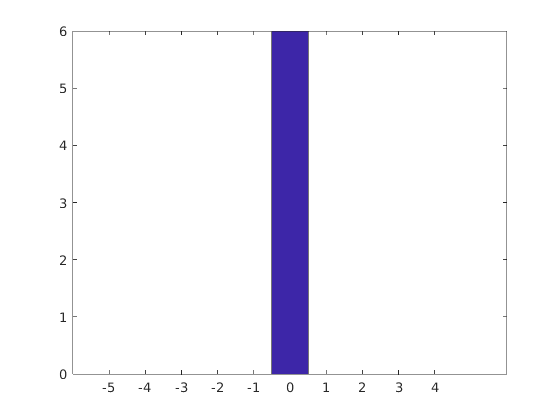

mitochondrialMoietyFraction = sum(arm.L(:,isMitochondrial),2)./sum(arm.L,2);
figure;
title('Fraction of moiety incidence that is mitochondrial')
hist(mitochondrialMoietyFraction)

bool= mitochondrialMoietyFraction==1;
C = cell(nnz(bool),8);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(arm.L(i,:)~=0);
        C(n,1:8) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),model.mets{ind(1)},model.metNames{ind(1)},model.metFormulas{ind(1)}};
        n=n+1;
    end
end

C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Examplemet','Examplename','Exampleformula'};
size(T,1)

ans = 0

disp(T)

### Transitive moiety, of sufficient mass, with moderate incidence

isTransititiveMoiety= strcmp('Transitive',moietyTypes);
isModerateIncidence = moietyIncidence>=7 & moietyIncidence<=100;
isSufficientMass = moietyMasses > 2;
isSufficientMinimalMassFraction = minimalMassFraction > 0.1;
bool = isTransititiveMoiety & isModerateIncidence & isSufficientMass & isSufficientMinimalMassFraction;
C = cell(nnz(bool),9);
n=1;
for i=1:size(arm.L,1)
    if bool(i)
        ind = find(strcmp(minimalMassMetabolite{i},model.mets));
        C(n,1:9) = {i,nnz(arm.L(i,:)),nnz(model.S((arm.L(i,:)~=0)',:)~=0),moietyFormulae{i},moietyMasses(i),minimalMassMetabolite{i},model.metNames{ind},model.metFormulas{ind},minimalMassFraction(i)};
        n=n+1;
    end
end

C=sortrows(C,9,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','metabolites','rxns','moietyformula','mass','Minimalmassmetabolite','Name','Formula','Massfraction'};
size(T,1)

ans = 0

disp(T)

## Individual moiety subnetwork

Examine the metabolites and reactions in an individual moiety subnetwork.

ind = min(size(arm.L,1),32);% anth moiety
mBool=arm.L(ind,:)~=0;
nnz(mBool)

ans = 5

rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
nnz(rBool)

ans = 6

Metabolites

bool=mBool;
C = cell(nnz(bool),5);
n=1;
for i=1:size(model.S,1)
    if bool(i)
        C(n,1:5) = {i,model.mets{i},model.metNames{i},model.metFormulas{i},metMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','met','name','formula','mass'};
disp(T)

    index        met           name          formula        mass 
    _____    ___________    ___________    ____________    ______

      7      {'34dhphe'}    {'34dhphe'}    {'C9H11NO4'}    197.07
      4      {'tyr_L'  }    {'tyr_L'  }    {'C9H11NO3'}    181.07
      9      {'dopa'   }    {'dopa'   }    {'C8H12NO2'}    154.09
      3      {'o2'     }    {'o2'     }    {'O2'      }     31.99
      6      {'h2o'    }    {'h2o'    }    {'H2O'     }    18.011



Reactions

formulas = printRxnFormula(model, model.rxns(rBool));

R1	phe_L + thbpt + o2 	->	tyr_L + dhbpt + h2o 
R2	thbpt + o2 + tyr_L 	->	dhbpt + h2o + 34dhphe 
R3	34dhphe + h 	->	dopa + co2 
EX_o2	o2 	<=>	
EX_h2o	h2o 	->	
EX_dopa	dopa 	->	


return

### Another Individual moiety subnetwork

Specify the index of a particular moiety

ind = min(size(arm.L,1),215);% Nicotinate moiety in iDopaNeuro1.
mBool=arm.L(ind,:)~=0;
nnz(mBool)
rBool = getCorrespondingCols(model.S, mBool, true(size(model.S,2),1), 'inclusive');
nnz(rBool)

Metabolites

bool=mBool;
C = cell(nnz(bool),5);
n=1;
for i=1:size(model.S,1)
    if bool(i)
        C(n,1:5) = {i,model.mets{i},model.metNames{i},model.metFormulas{i},metMasses(i)};
        n=n+1;
    end
end
C=sortrows(C,5,'descend');
T=cell2table(C);
T.Properties.VariableNames={'index','met','name','formula','mass'};
disp(T)

Reactions

formulas = printRxnFormula(model, model.rxns(rBool));

Save analysis results

save([resultsDir  modelName '_ConservedMoietiesAnalysis.mat'])